## Problem 12

omega = 15;
zeta = 1; % A1=1, A2=0
T_L = 0

T_L = 0

Jeff1=0.0198; % kgm^2
Jeff2=0.0242; % kgm^2
Jeff3=0.0027; % kgm^2
Jeff4=0.00038; % kgm^2
qr_1 = 0.34; % rad/s
qr_2 = 0.34; % rad/s
qr_3 = 0.34; % m
qr_4 = 0.34; % rad/s
k_T = 0.17 % Nm/V

k_T = 0.1700

f = 0.000024 % Nm/(rad/s)

f = 2.4000e-05


Kp_1 = (omega^2*Jeff1)/k_T

Kp_1 = 26.2059

Kp_2 = (omega^2*Jeff2)/k_T

Kp_2 = 32.0294

Kp_3 = (omega^2*Jeff3)/k_T

Kp_3 = 3.5735

Kp_4 = (omega^2*Jeff4)/k_T

Kp_4 = 0.5029


Kd_1 = (2*zeta*omega*Jeff1-f)/k_T

Kd_1 = 3.4940

Kd_2 = (2*zeta*omega*Jeff2-f)/k_T

Kd_2 = 4.2704

Kd_3 = (2*zeta*omega*Jeff3-f)/k_T

Kd_3 = 0.4763

Kd_4 = (2*zeta*omega*Jeff4-f)/k_T

Kd_4 = 0.0669


J1=Jeff1/k_T

J1 = 0.1165

J2=Jeff2/k_T

J2 = 0.1424

J3=Jeff3/k_T

J3 = 0.0159

J4=Jeff4/k_T

J4 = 0.0022


B=f/k_T

B = 1.4118e-04

% simulink = sim('problem12.slx',10);   % start simulation
% %open_system('problem12/Scope')   % open scope
% q1 = simulink.get('q1');
% q2 = simulink.get('q2');
% q3 = simulink.get('q3');
% q4 = simulink.get('q4');
% qrData=ones(length(q4.Data),1)*0.34;
% plot(q1.Time,q1.Data), hold on
% plot(q2.Time,q2.Data), hold on
% plot(q3.Time,q3.Data), hold on
% plot(q4.Time,q4.Data), hold on
% plot(q4.Time,qrData)
% legend('q1','q2','q3','q4','qr')
% xlabel('Time [s]') 
% ylabel('Joint position')
% title('Plot A_1 with dampening ratio ζ=1')

## Problem 13

n=53;
Jm=1320e-7;
syms q1 q2 q3 q4;

I1yy=0.00392;

m2=8.1;
L2=1.7;
I2=1.98342;
I2zz=0.06534;

m3=4.9;
L3=1.65;
I3=1.12492;
I3yy=0.02646;

m4=2.2;
a4=0.98;
I4=0.17607;

D2=0.34;

K0=m2*(L2/2-D2)^2+m3*(L3/2)^2;
K1=(I4+(m4*a4^2)/4)/2;
K2=(I2-I2zz+I3-I3yy+K0)/2;
K3=I2+I3+K0+2*K1;
K4=m3+m4;
K5=(2*I1yy+I2zz+I3yy+K3)/2;
f1=(K4*q3^2)/2-m3*L3*q3/2;
f2=m4*a4*q3;
f=a4*m4*cos(q4)/2;

g=9.81;

x0 = [0;pi/2;2;pi/2];
A = [ ];
b = [ ];
Aeq = [ ];
beq = [ ];
lb = [-pi;pi/6;1.35;-pi/2];
ub = [pi;3*pi/4;3;5*pi/4];

TL1p=0;         % Setup positive TL functions, depending on qi=x(i)
TL2p=@(x)-(m4*a4*cos(x(2)+x(4))/2+(m2*(D2-L2/2)+m3*(L3/2-x(3))-m4*x(3))*sin(x(2)));
TL3p=@(x)-((m3+m4)*cos(x(2)));
TL4p=@(x)-(a4*m4*cos(x(2)+x(4))/2);

[xTL2p,fvalTL2p] = fmincon(TL2p,x0,A,b,Aeq,beq,lb,ub) % Find maximum value of functions TL


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xTL2p =     0.0000
    0.5236
    1.3500
   -0.5236


fvalTL2p = 3.7588

[xTL3p,fvalTL3p] = fmincon(TL3p,x0,A,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xTL3p =     0.0000
    0.5236
    2.0264
    1.5664


fvalTL3p = -6.1488

[xTL4p,fvalTL4p] = fmincon(TL4p,x0,A,b,Aeq,beq,lb,ub)


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xTL4p =          0
    1.5708
    2.0000
    1.5708


fvalTL4p = 1.0780

T1=g*TL1p

T1 = 0

T2=-fvalTL2p*g     % As we found the max using fmincon, we have to invert the answers

T2 = -36.8734

T3=-fvalTL3p*g

T3 = 60.3195

T4=-fvalTL4p*g

T4 = -10.5752

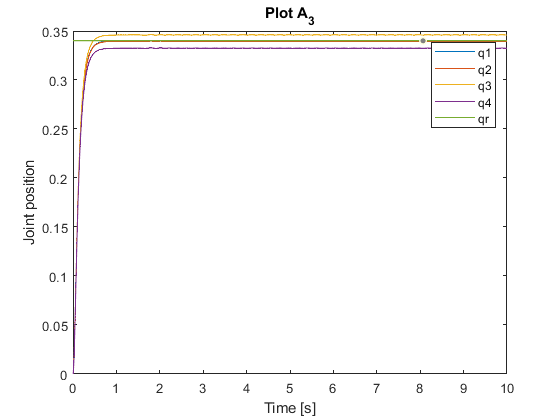

simulink = sim('problem13',10);   % start simulation
%open_system('problem12/Scope')   % open scope
q1 = simulink.get('q1');
q2 = simulink.get('q2');
q3 = simulink.get('q3');
q4 = simulink.get('q4');
qrData=ones(length(q4.Data),1)*0.34;
plot(q1.Time,q1.Data), hold on
plot(q2.Time,q2.Data), hold on
plot(q3.Time,q3.Data), hold on
plot(q4.Time,q4.Data), hold on
plot(q4.Time,qrData)
legend('q1','q2','q3','q4','qr')
xlabel('Time [s]') 
ylabel('Joint position')
title('Plot A_3')


diff1=qr_1-q1.Data(end);
diff2=qr_2-q2.Data(end);
diff3=qr_3-q3.Data(end);
diff4=qr_4-q4.Data(end);